clear; clc; close all;
work_dir=fileparts(mfilename('fullpath')); addpath(work_dir);
case_dir=week2_environment(work_dir);
Stu_ID=206231315;

## 1. 规划模型与参数

V_min_Lin=0.960; energy_cost_multiplier=1;
Base=week2_solve(Stu_ID,case_dir,V_min_Lin,energy_cost_multiplier);
assert(Base.Feasible,'基准规划求解失败：%s',Base.Info);
assert(Base.Check.Passed && Base.Check.ACVoltagePassed,'基准规划或交流电压未通过校核。');
disp(Base.Configuration);
CostComponents=table(Base.Cost.InvestmentAnnual,Base.Cost.MaintenanceAnnual,...
    Base.Cost.GridAnnual,Base.Cost.TotalAnnual,Base.Cost.ACTotalAnnual,...
    'VariableNames',{'Investment_YuanPerYear','Maintenance_YuanPerYear',...
    'LinearGrid_YuanPerYear','ModelTotal_YuanPerYear','ACActualTotal_YuanPerYear'});
disp(CostComponents);

实际MATLAB计算结果：储能231 梁宏熙 206231315
候选节点  建站  额定功率/MW  额定能量/MWh
       4     0            0             0
       9     1            1             1
      14     0            0             0
年综合费用：12535888.168288 元/年
求解器：MATLAB intlinprog (highs)；exitflag=1；relativegap=0


## 2. 全网24小时交流校核

ACCheck=table(Base.MinBaseVoltage,Base.MinLinearVoltage,Base.MinACVoltage,...
    Base.MaxACVoltage,Base.MaxVoltageError,Base.LossBenefitAnnual,...
    Base.Check.ACConverged,Base.Check.ACVoltagePassed,...
    'VariableNames',{'MinBaseVoltage','MinLinearVoltage','MinACVoltage','MaxACVoltage',...
    'MaxVoltageError','LossBenefit_YuanPerYear','AllACConverged','ACVoltagePassed'});
disp(ACCheck);
disp(struct2table(Base.Check));

24小时基准与配置后交流潮流均收敛。
交流电压范围：[0.9585015725, 1.0000000000] p.u.
全网最大线性/交流电压偏差：0.001498427485 p.u.
{
  "PowerBalanceMW": 1.5959455978986625e-14,
  "ReactiveBalanceMvar": 8.673617379884035e-17,
  "EnergyBalanceMWh": 1.1102230246251565e-16,
  "VoltageEquation": 3.5041414214731503e-16,
  "BigMProduct": 0,
  "MaxSimultaneousMW": 0,
  "EndSoCError": 0,
  "BinaryError": 0,
  "BoundsViolation": 0,
  "Passed": true,
  "ACConverged": true,
  "ACVoltagePassed": true,
  "ACPowerBalanceMW": 7.053138073587206e-10
}


## 3. 大M法手算验证：SoC=0.65

BigM=table([0;1],[0;0.20],[0;0.80],[-0.15;0.65],[0.45;0.65],[0;0.65],...
    'VariableNames',{'w','Bound1_Lower','Bound2_Upper','Bound3_Lower','Bound4_Upper','ExactDelta'});
disp(BigM);

SoC=0.65：
w=0：0≤δ≤0，-0.15≤δ≤0.45，故δ=0。
w=1：0.20≤δ≤0.80，0.65≤δ≤0.65，故δ=0.65。


## 4. 投资成本和电压下限灵敏度

settings=[0.96 0.5;0.96 1;0.96 1.5;0.96 2;0.95 1;0.965 1];
Studies=cell(size(settings,1),1);
for n=1:size(settings,1)
    if all(abs(settings(n,:)-[0.96,1])<1e-12)
        Studies{n}=Base;
    else
        Studies{n}=week2_solve(Stu_ID,case_dir,settings(n,1),settings(n,2));
    end
    save(fullfile(work_dir,'Week2_study_checkpoint.mat'),'Base','Studies');
end
Sensitivity=week2_sensitivity_table(Studies);
disp(Sensitivity);

VminLin   cE倍率   最优节点   总容量/MWh    年费用/万元     AC最低电压
  0.960    0.50        9            1    1251.382146   0.95837419
  0.960    1.00        9            1    1253.588817   0.95850157
  0.960    1.50        9            1    1255.795488   0.95837419
  0.960    2.00        9            1    1258.002159   0.95837419
  0.950    1.00       []            0    1239.814238   0.95670796
  0.965    1.00        9            2    1274.620258   0.96378189


## 5. 标准化评测文件

沿用模板规定的Result变量名及六个字段，不增加或重命名字段。 Opt_Sites保存候选节点序号，实际节点为Base.CandidateBuses(Result.Opt_Sites)。

Result.StuID=Stu_ID;
Result.Obj_Value=Base.Cost.TotalAnnual;
Result.Opt_Sites=find(Base.Z==1);
Result.Opt_P_rated=Base.RatedPowerMW;
Result.Opt_E_rated=Base.RatedEnergyMWh;
Result.Max_V_Err=Base.MaxVoltageError;
save(fullfile(work_dir,'result_summary.mat'),'Result');
save(fullfile(work_dir,'Week2_results_206231315.mat'),'Base','Studies','Sensitivity','BigM');
writetable(Base.Configuration,fullfile(work_dir,'Week2_Configuration_206231315.csv'));
writetable(Sensitivity,fullfile(work_dir,'Week2_Sensitivity_206231315.csv'));
Summary=struct('StudentID',Stu_ID,'Name','梁宏熙','Class','储能231','Base',Base,...
    'Sensitivity',table2struct(Sensitivity),'BigM',table2struct(BigM));
fid=fopen(fullfile(work_dir,'Week2_summary_206231315.json'),'w','n','UTF-8');
assert(fid~=-1,'无法保存结果摘要。'); fprintf(fid,'%s',jsonencode(Summary,'PrettyPrint',true)); fclose(fid);

## 6. 规划前后电压、配置费用、运行曲线与灵敏度图

白底600dpi PNG、矢量PDF及可编辑FIG；绘图不依赖R2025a的theme函数。

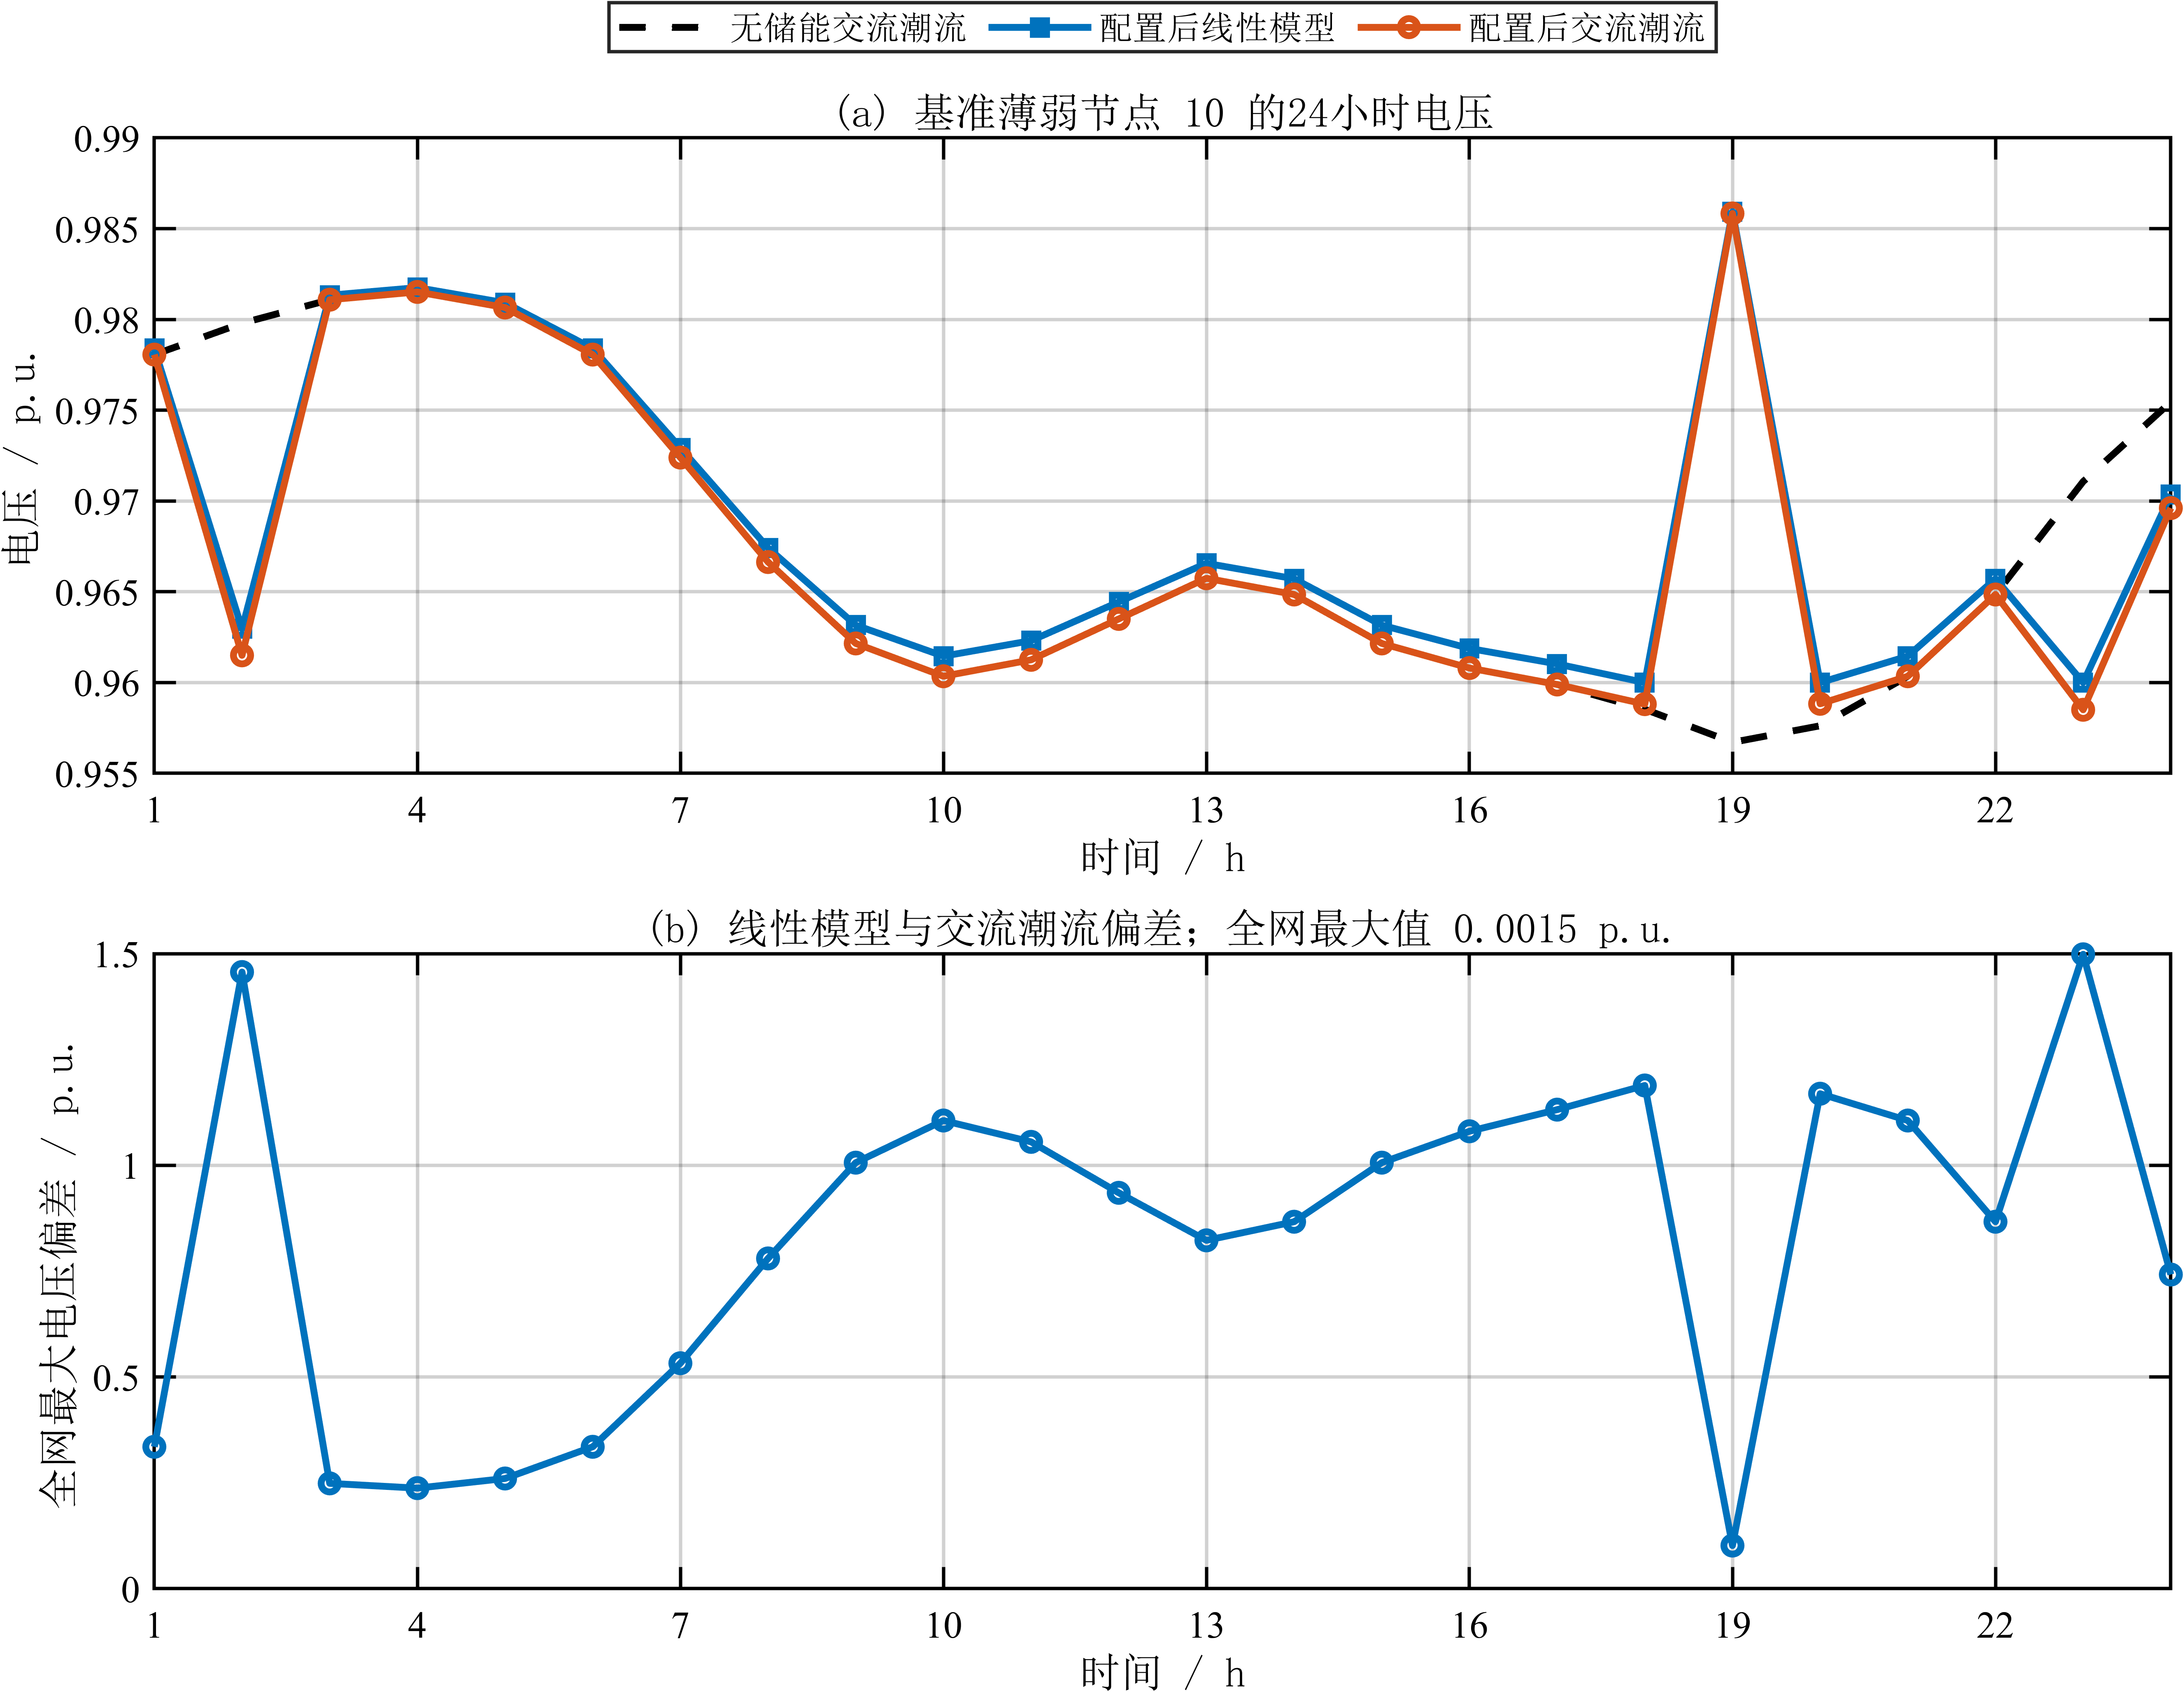

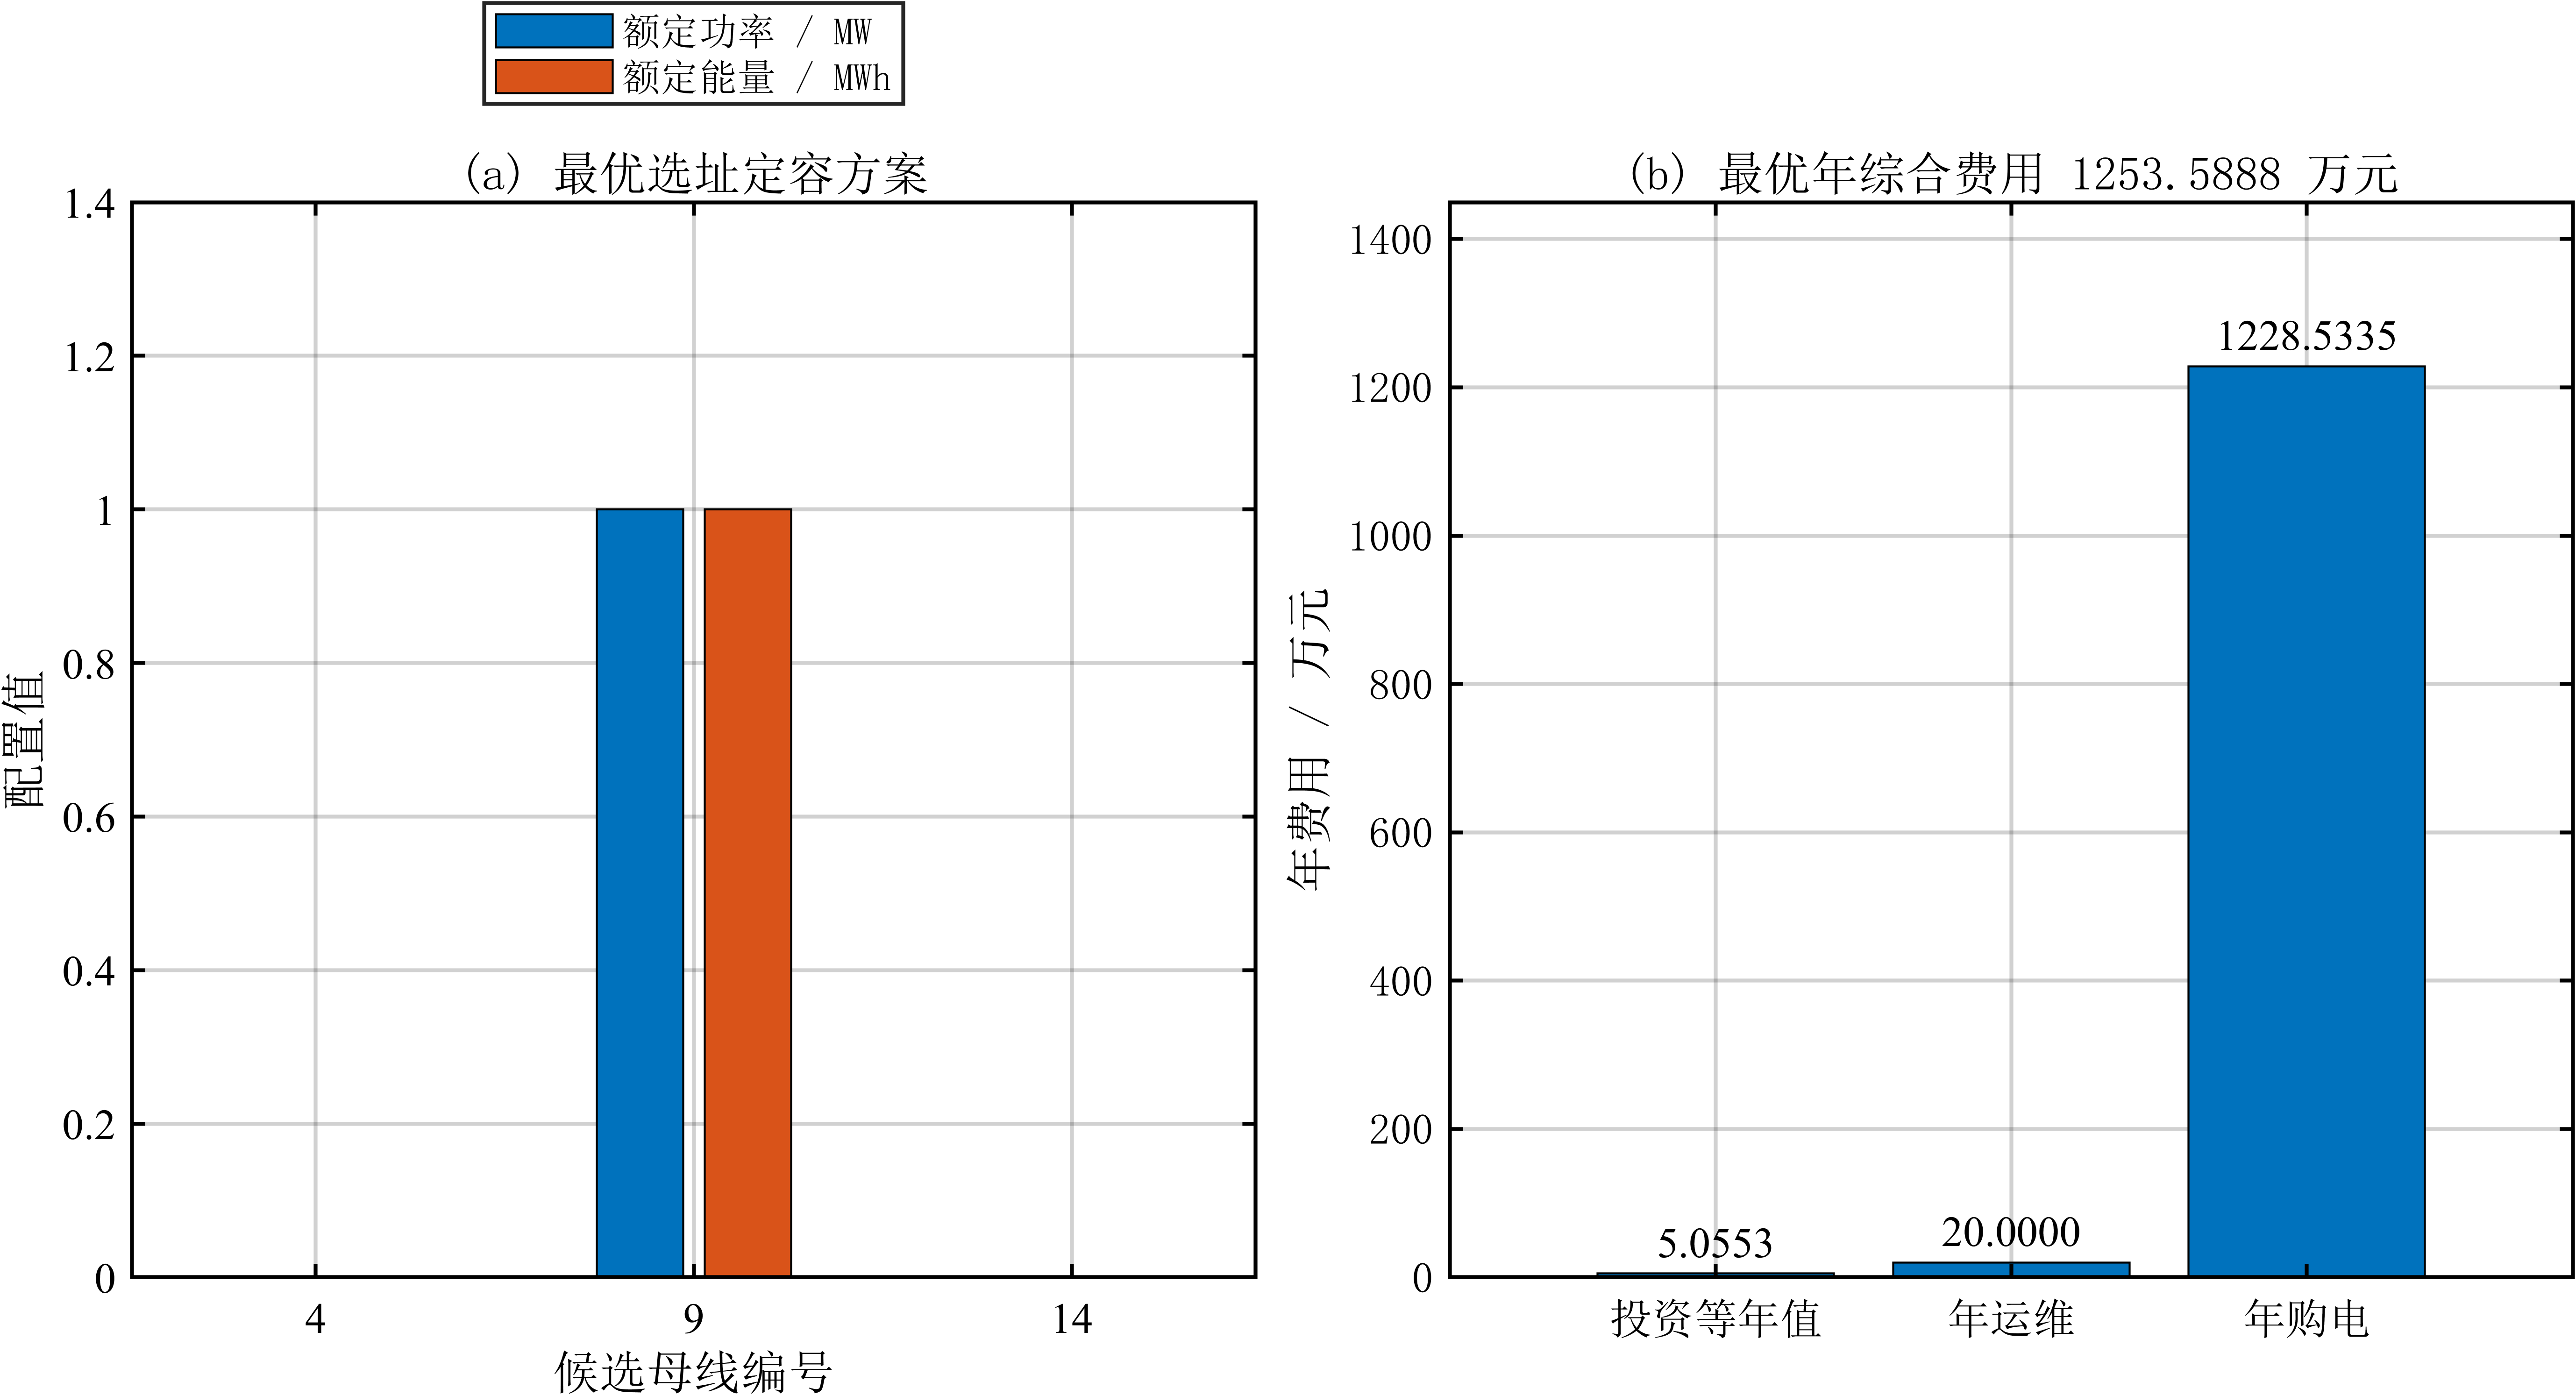

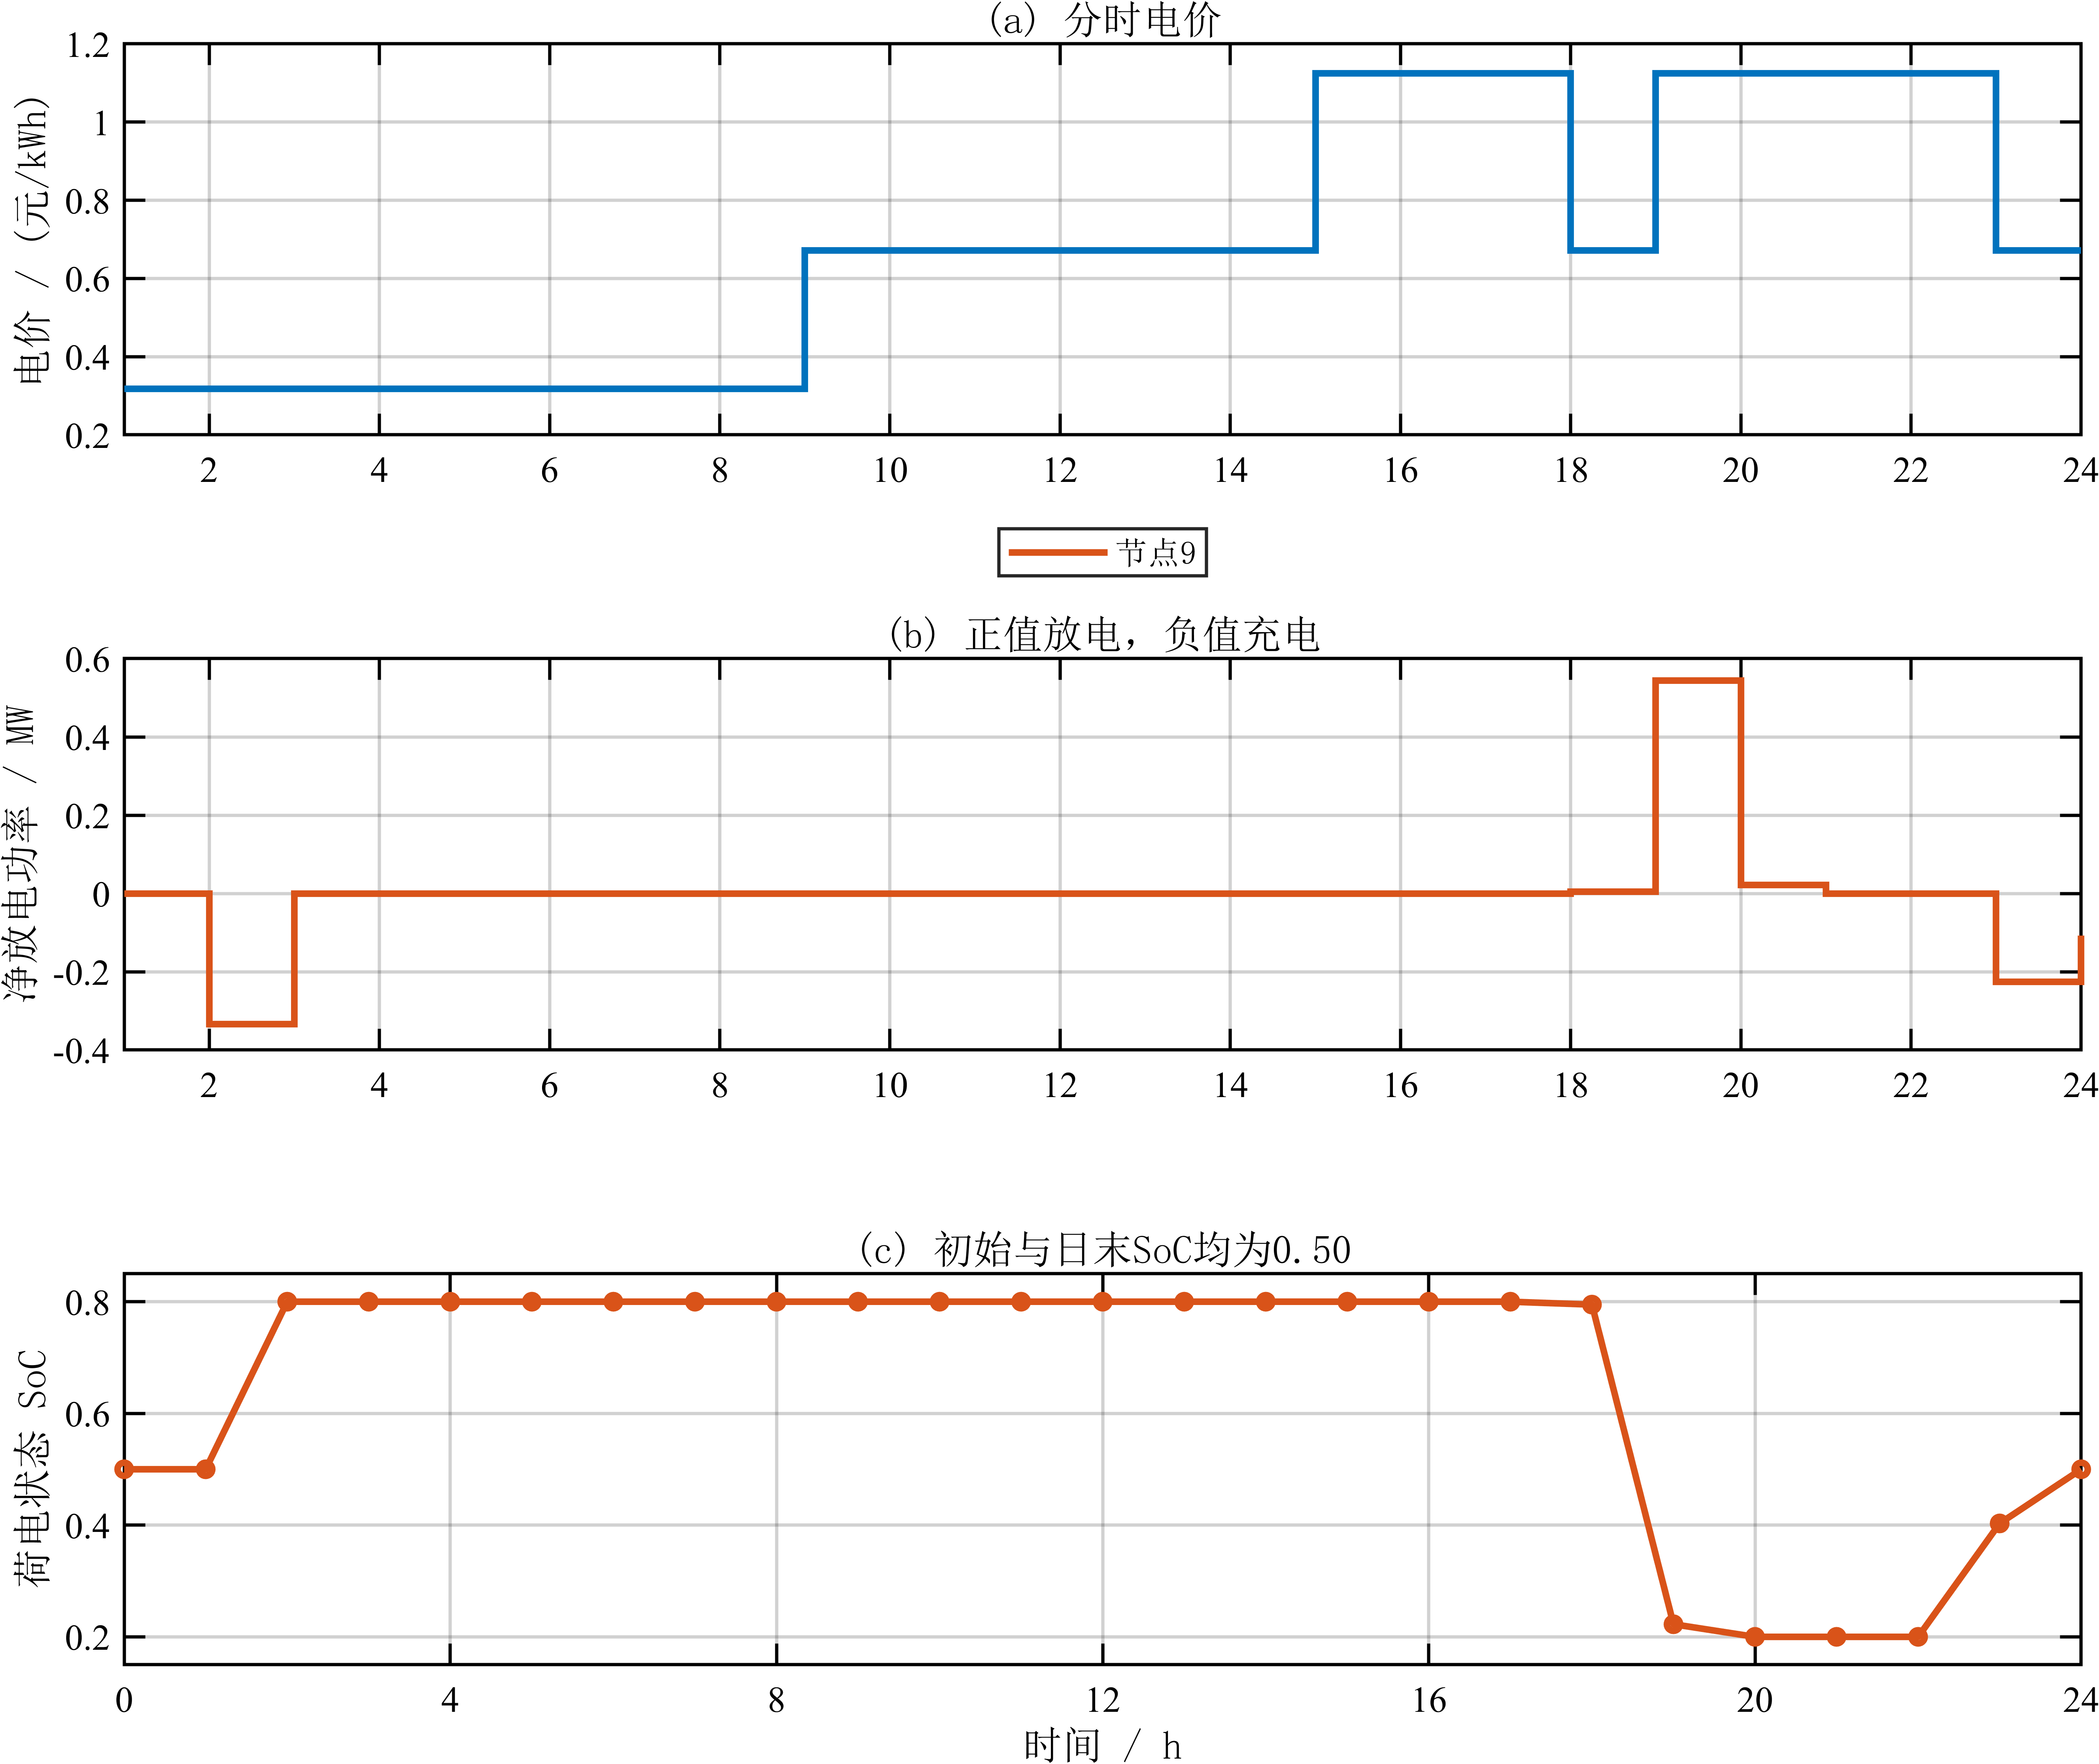

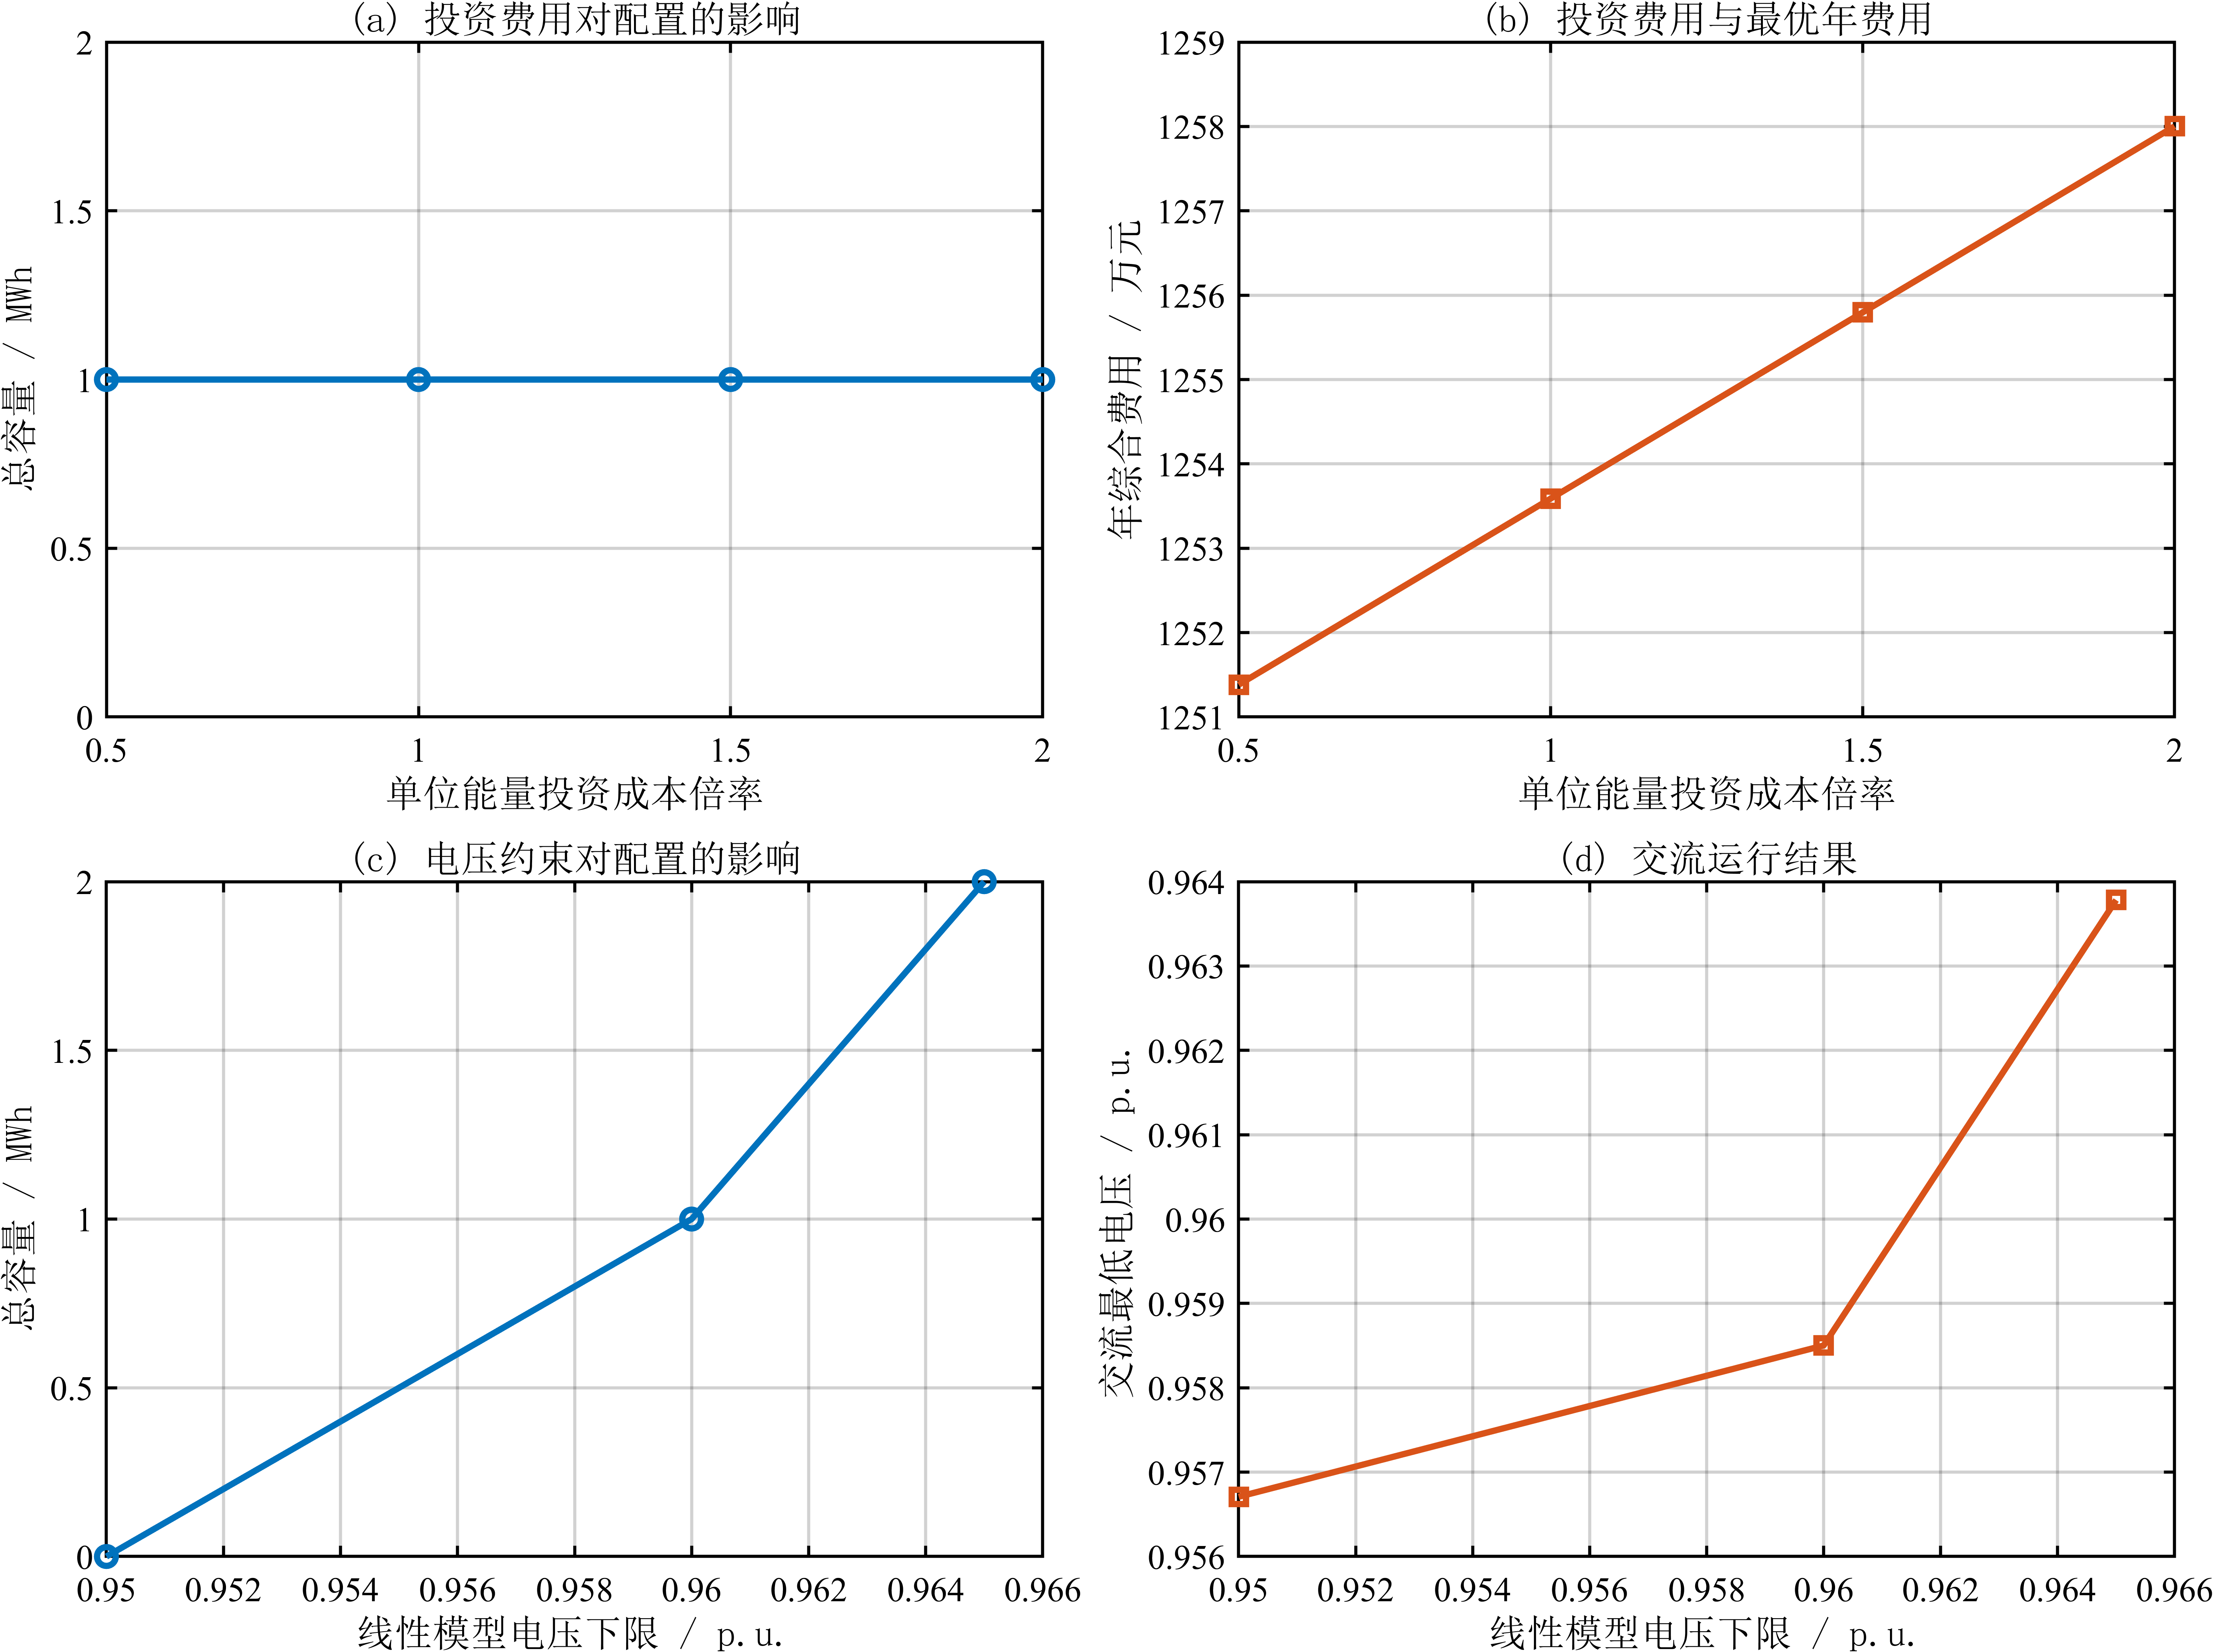

Figures=week2_figures(work_dir,Base,Sensitivity);

fprintf('\n任务四已完成：模型年费用 %.6f 万元，交流电压[%.8f, %.8f] p.u.。\n',...
    Base.Cost.TotalAnnual/1e4,Base.MinACVoltage,Base.MaxACVoltage);
fprintf('标准结果文件：%s\n',fullfile(work_dir,'result_summary.mat'));